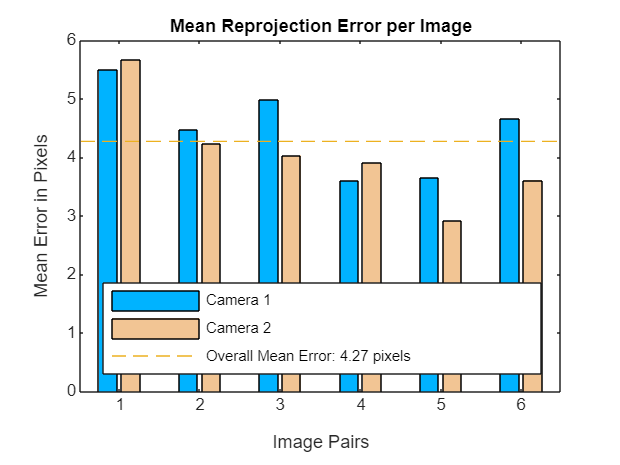

% Auto-generated by stereoCalibrator app on 10-Dec-2024
%-------------------------------------------------------


% Define images to process
imageFileNames1 = {'C:\Users\nitis\OneDrive\Documents\Nav iphone 15plus (Left)\SCNav3.jpg',...
    'C:\Users\nitis\OneDrive\Documents\Nav iphone 15plus (Left)\SCNav4.jpg',...
    'C:\Users\nitis\OneDrive\Documents\Nav iphone 15plus (Left)\SCNav5.jpg',...
    'C:\Users\nitis\OneDrive\Documents\Nav iphone 15plus (Left)\SCNav6.jpg',...
    'C:\Users\nitis\OneDrive\Documents\Nav iphone 15plus (Left)\SCNav7.jpg',...
    'C:\Users\nitis\OneDrive\Documents\Nav iphone 15plus (Left)\SCNav8.jpg',...
    };
imageFileNames2 = {'C:\Users\nitis\OneDrive\Documents\Nitish iphone 15 (Right)\SCNitish3.jpg',...
    'C:\Users\nitis\OneDrive\Documents\Nitish iphone 15 (Right)\SCNitish4.jpg',...
    'C:\Users\nitis\OneDrive\Documents\Nitish iphone 15 (Right)\SCNitish5.jpg',...
    'C:\Users\nitis\OneDrive\Documents\Nitish iphone 15 (Right)\SCNitish6.jpg',...
    'C:\Users\nitis\OneDrive\Documents\Nitish iphone 15 (Right)\SCNitish7.jpg',...
    'C:\Users\nitis\OneDrive\Documents\Nitish iphone 15 (Right)\SCNitish8.jpg',...
    };

% Detect calibration pattern in images
detector = vision.calibration.stereo.CheckerboardDetector();
[imagePoints, imagesUsed] = detectPatternPoints(detector, imageFileNames1, imageFileNames2);

% Generate world coordinates for the planar pattern keypoints
squareSize = 21;  % in units of 'millimeters'
worldPoints = generateWorldPoints(detector, 'SquareSize', squareSize);

% Read one of the images from the first stereo pair
I1 = imread(imageFileNames1{1});
[mrows, ncols, ~] = size(I1);

% Calibrate the camera
[stereoParams, pairsUsed, estimationErrors] = estimateCameraParameters(imagePoints, worldPoints, ...
    'EstimateSkew', false, 'EstimateTangentialDistortion', false, ...
    'NumRadialDistortionCoefficients', 2, 'WorldUnits', 'millimeters', ...
    'InitialIntrinsicMatrix', [], 'InitialRadialDistortion', [], ...
    'ImageSize', [mrows, ncols]);

% View reprojection errors
h1=figure; showReprojectionErrors(stereoParams);

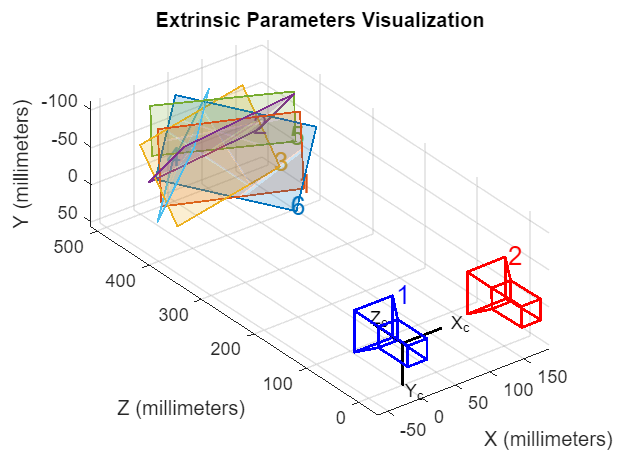


% Visualize pattern locations
h2=figure; showExtrinsics(stereoParams, 'CameraCentric');


% Display parameter estimation errors
displayErrors(estimationErrors, stereoParams);


			Standard Errors of Estimated Stereo Camera Parameters
			-----------------------------------------------------

Camera 1 Intrinsics
-------------------
Focal length (pixels):   [ 4289.1973 +/- 30.3031    4236.0408 +/- 29.5656 ]
Principal point (pixels):[ 2955.5850 +/- 22.6547    2177.3457 +/- 14.1069 ]
Radial distortion:       [    0.1606 +/- 0.0321       -0.6745 +/- 0.1139  ]

Camera 1 Extrinsics
-------------------
Rotation vectors:
                         [    0.7480 +/- 0.0089       -0.0078 +/- 0.0063        2.9992 +/- 0.0019  ]
                         [   -0.1021 +/- 0.0088       -1.0875 +/- 0.0054        2.9171 +/- 0.0031  ]
                         [   -0.1555 +/- 0.0085        0.8233 +/- 0.0055        2.9205 +/- 0.0029  ]
                         [    1.0999 +/- 0.0071        0.4879 +/- 0.0058       -2.6305 +/- 0.0039  ]
                         [    0.7866 +/- 0.0083       -0.6212 +/- 0.0055        2.7795 +/- 0.0034  ]
                         [   -0.9932 +/- 0.0071     


% You can use the calibration data to rectify stereo images.
I2 = imread(imageFileNames2{1});


imageLeft = imread("IMG_4765.jpg")

imageLeft = 4284×5712×3 uint8 array
imageLeft(:,:,1) =

  Columns 1 through 5,461

   229   224   219   217   219   220   220   219   217   222   223   222   222   220   219   220   221   226   227   221   215   215   216   216   218   223   223   219   220   222   220   218   216   220   218   214   217   220   217   215   219   221   217   214   216   220   220   220   214   218   216   215   216   214   212   217   214   214   216   217   215   214   216   219   214   216   216   214   214   216   216   214   217   218   218   218   217   216   213   210   211   216   217   216   216   216   215   216   210   219   219   214   214   215   214   217   214   215   215   217   221   220   217   218   212   212   215   216   213   213   215   213   213   212   211   213   215   215   213   212   211   213   213   211   210   210   210   209   208   203   205   206   199   196   202   208   206   206   206   205   206   207   206   205   205   209   211   207   204   205   207   206   20

imageRight = imread("IMG_1325.jpg")

imageRight = 4284×5712×3 uint8 array
imageRight(:,:,1) =

  Columns 1 through 5,461

   193   191   197   213   223   222   219   218   214   210   206   203   201   197   195   195   196   197   194   189   190   193   195   196   198   199   199   202   208   212   208   200   181   169   156   149   143   141   143   148   149   148   150   154   159   161   163   164   167   181   185   185   195   198   196   197   204   215   222   217   211   214   215   210   208   210   211   212   214   214   209   203   204   208   210   209   206   201   202   208   211   205   203   208   208   203   204   209   207   208   207   205   206   211   215   215   208   208   211   213   213   212   214   217   209   202   204   206   203   209   216   214   212   212   210   208   210   210   208   208   206   214   214   209   210   210   210   214   210   213   214   209   206   212   214   209   202   203   207   210   210   210   210   208   206   209   212   211   210   211   212   212   

    
[J1, J2, reprojectionMatrix] = rectifyStereoImages(imageLeft, imageRight,stereoParams);

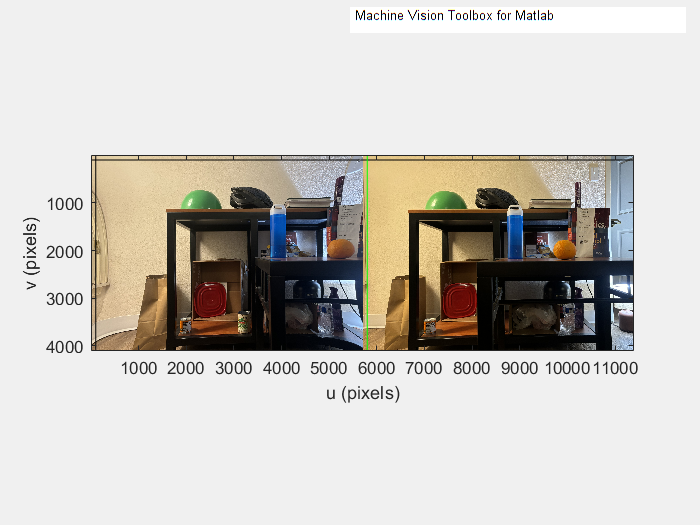


stdisp(J1,J2)





% See additional examples of how to use the calibration data.  At the prompt type:
% showdemo('StereoCalibrationAndSceneReconstructionExample')
% showdemo('DepthEstimationFromStereoVideoExample')




